# 6.1 巴特沃思模拟低通：幅度平方函数、极点在圆上、分母多项式表、按指标定 N 与 Ωc

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。设计公式自写（dsp_butter_analog 等，只用基础 MATLAB）， 装了 Signal Processing Toolbox 时顺带与 butter 对照。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
here = fileparts(mfilename('fullpath')); if endsWith(here, 'mlx'), here = fileparts(here); end
if ~exist(fullfile(here, 'dsp_freqz.m'), 'file'), here = fileparts(which('dsp_freqz')); end   % Live Script 里 mfilename 为空时靠路径找
codedir = here; addpath(codedir); outdir = fullfile(codedir, 'results'); if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：幅度平方函数 `Ha(jΩ)`² = 1/[1+(Ω/Ωc)^{2N}]，N=1…6（教材式 (6.1.4)、图 6.1.3）

W = linspace(0, 3, 1500); Wc = 1;
A2 = zeros(6, numel(W)); for N = 1:6, A2(N, :) = 1./(1 + (W/Wc).^(2*N)); end
% 三个必然事实：Ω=0 时为 1；Ω=Ωc 时为 1/2（3 dB）；N 越大越接近理想低通

## 演示2：极点：Ha(s)Ha(−s) 的 2N 个根均布在半径 Ωc 的圆上，取左半平面的 N 个（教材式 (6.1.5)—(6.1.7)、图 6.1.4）

N3 = 3; all6 = Wc*exp(1i*pi*(0.5 + (2*(1:2*N3) - 1)/(2*N3)));   % 2N 个根
[b3, a3, p3] = dsp_butter_analog(N3, Wc);                           % 左半平面 N 个
[b6, a6, p6] = dsp_butter_analog(6, Wc);
angDeg3 = sort(mod(angle(p3)*180/pi, 360));                          % 120°, 180°, 240°

## 演示3：把极点乘回去得到分母多项式，与教材表 6.1.1 对照（Ωc=1）

tab = {[1 1], [1 1.4142 1], [1 2 2 1], [1 2.6131 3.4142 2.6131 1], ...
       [1 3.2361 5.2361 5.2361 3.2361 1], [1 3.8637 7.4641 9.1416 7.4641 3.8637 1]};
tabErr = zeros(1, 6); for N = 1:6, [~, a] = dsp_butter_analog(N, 1); tabErr(N) = max(abs(a - tab{N})); end
errSPT = NaN; if exist('butter', 'file') == 2, [~, aS] = butter(6, 1, 's'); errSPT = max(abs(aS - a6)); end

## 演示4：按指标定阶与定 Ωc（教材例 6.5 第 (2) 步）：Ωp=0.2π 处衰减 ≤1 dB，Ωs=0.3π 处 ≥15 dB

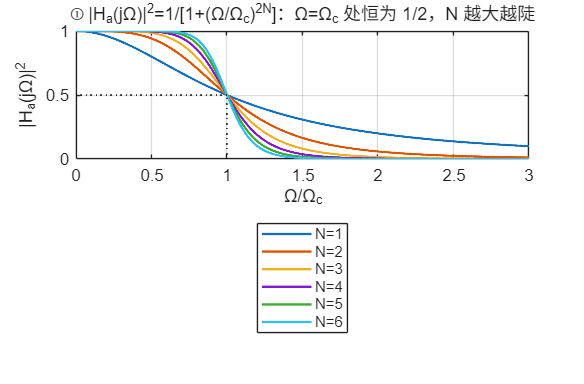

Wp = 0.2*pi; Ws = 0.3*pi; ap = 1; as = 15;
Nexact = log10((10^(as/10) - 1)/(10^(ap/10) - 1)) / (2*log10(Ws/Wp));   % 由式 (6.2.15)(6.2.16) 相除
N = ceil(Nexact);
WcP = Wp/(10^(ap/10) - 1)^(1/(2*N));      % 由通带指标定 Ωc（阻带留有余量）
WcS = Ws/(10^(as/10) - 1)^(1/(2*N));      % 由阻带指标定 Ωc（通带留有余量）
[bN, aN] = dsp_butter_analog(N, WcP); [bN5, aN5] = dsp_butter_analog(N - 1, WcP);
attP = -20*log10(abs(dsp_freqs(bN, aN, Wp))); attS = -20*log10(abs(dsp_freqs(bN, aN, Ws)));
attS5 = -20*log10(abs(dsp_freqs(bN5, aN5, Ws)));
Wd = linspace(0, pi, 1024);

if ~LIVE, f1 = figure('Name','01 巴特沃思','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(W, A2, 'LineWidth', 1.4); hold on; plot([1 1], [0 0.5], 'k:'); plot([0 1], [0.5 0.5], 'k:');
grid on; xlabel('Ω/Ω_c'); ylabel('|H_a(jΩ)|^2'); title('① |H_a(jΩ)|^2=1/[1+(Ω/Ω_c)^{2N}]：Ω=Ω_c 处恒为 1/2，N 越大越陡');
legend(compose('N=%d', 1:6));

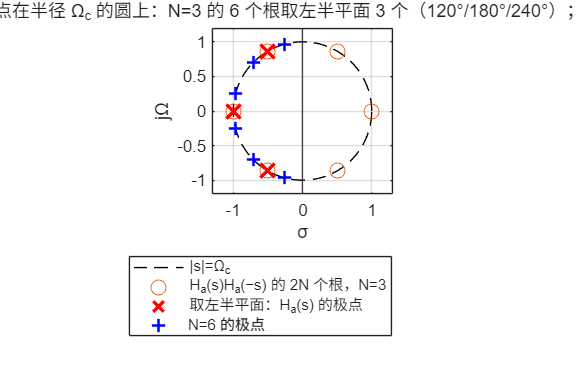

newpanel(); tt = linspace(0, 2*pi, 400); plot(cos(tt), sin(tt), 'k--'); hold on; axis equal; grid on;
plot(real(all6), imag(all6), 'o', 'MarkerSize', 9); plot(real(p3), imag(p3), 'rx', 'MarkerSize', 12, 'LineWidth', 2);
plot(real(p6), imag(p6), 'b+', 'MarkerSize', 8, 'LineWidth', 1.5); xline(0, 'k-');
xlim([-1.3 1.3]); ylim([-1.2 1.2]); xlabel('σ'); ylabel('jΩ');
title(sprintf('② 极点在半径 Ω_c 的圆上：N=3 的 6 个根取左半平面 3 个（%d°/%d°/%d°）；+ 为 N=6', round(angDeg3)));
legend('|s|=Ω_c', 'H_a(s)H_a(−s) 的 2N 个根，N=3', '取左半平面：H_a(s) 的极点', 'N=6 的极点');

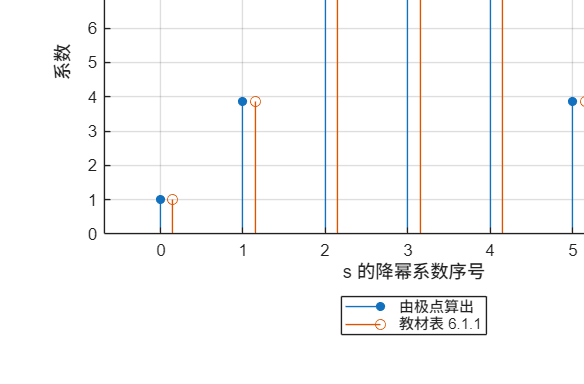

newpanel(); stem(0:6, a6, 'filled', 'MarkerSize', 5); hold on; stem((0:6)+0.15, tab{6}, 'MarkerSize', 6);
grid on; xlabel('s 的降幂系数序号'); ylabel('系数');
title(sprintf('③ 极点乘回去得分母多项式：N=6 与教材表 6.1.1 最大差 %.1e', tabErr(6)));
legend('由极点算出', '教材表 6.1.1');

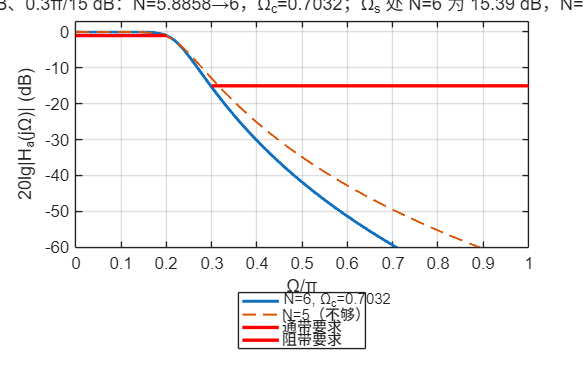

newpanel(); plot(Wd/pi, 20*log10(abs(dsp_freqs(bN, aN, Wd))), 'LineWidth', 1.8); hold on;
plot(Wd/pi, 20*log10(abs(dsp_freqs(bN5, aN5, Wd))), '--', 'LineWidth', 1.2);
plot([0 Wp/pi], [-ap -ap], 'r-', 'LineWidth', 2); plot([Ws/pi 1], [-as -as], 'r-', 'LineWidth', 2);
grid on; ylim([-60 3]); xlabel('Ω/π'); ylabel('20lg|H_a(jΩ)| (dB)');
title(sprintf('④ 0.2π/1 dB、0.3π/15 dB：N=%.4f→%d，Ω_c=%.4f；Ω_s 处 N=6 为 %.2f dB，N=5 为 %.2f dB', Nexact, N, WcP, attS, attS5));
legend(sprintf('N=%d, Ω_c=%.4f', N, WcP), sprintf('N=%d（不够）', N-1), '通带要求', '阻带要求');

if ~LIVE, sgtitle('巴特沃思：幅度平方函数只有一个参数 N 决定形状，极点在圆上；按指标先定 N 再定 Ω_c'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '01-butterworth.png'), 'Resolution', 150); end

## 教师核验

A2c = 1./(1 + (Wc/Wc).^(2*(1:6)));
assert(all(abs(A2(:, 1) - 1) < 1e-12) && all(abs(A2c - 0.5) < 1e-12), 'Ω=0、Ω=Ω_c 处的值不对');
assert(max(abs(angDeg3 - [120 180 240])) < 1e-9, 'N=3 极点角度不符');
assert(max(tabErr) < 6e-5, '与表 6.1.1 不符');
assert(abs(Nexact - 5.8858) < 1e-3 && N == 6 && abs(WcP - 0.7032) < 1e-3, '定阶结果与例 6.5 不符');
assert(attP <= ap + 1e-9 && attS >= as && attS5 < as, '指标核验不符');
assert(isnan(errSPT) || errSPT < 1e-9, '与 butter 不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'poles_N3_deg', angDeg3, 'a_N6', a6, 'table_err_N1_6', tabErr, 'err_vs_butter', errSPT, ...
    'N_exact', Nexact, 'N', N, 'Wc_from_passband', WcP, 'Wc_from_stopband', WcS, 'att_wp_dB', attP, 'att_ws_dB', attS, 'att_ws_dB_N5', attS5, ...
    'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-butterworth.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

       matlab_version: '25.2.0.3360999 (R2025b) Update 7'
               run_at: '2026-09-18 21:31:07'
         poles_N3_deg: [120.0000 180 240]
                 a_N6: [1 3.8637 7.4641 9.1416 7.4641 3.8637 1]
       table_err_N1_6: [0 1.3562e-05 8.8818e-16 2.5930e-05 3.2023e-05 2.0173e-05]
        err_vs_butter: 5.3291e-15
              N_exact: 5.8858
                    N: 6
     Wc_from_passband: 0.7032
     Wc_from_stopband: 0.7087
            att_wp_dB: 1.0000
            att_ws_dB: 15.3901
         att_ws_dB_N5: 12.9451
    all_checks_passed: 1


课堂图已保存到：G:\2026-Agent\数字信号处理\课程网站\ch6\code\results



function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end